Setting the amount of neurons

clear all
% Created by Eugene M. Izhikevich, February 25, 2003
Ne=800;                 % Excitatory neurons
Ni=200;                 % Inhibitory neurons
re=rand(Ne,1);          % Random seed for each Excitatory neuron
ri=rand(Ni,1);          % Random seed for each Inhibitory neuron
steps=1000;             % Number of steps to perform

Setting the a,b,c and d coeficients:

- The parameter `a` describes the time scale of the recovery variable `u` . Smaller values result in slower recovery. A typical value is `a = 0.02`.

- The parameter `b` describes the sensitivity of the recovery variable `u` to the subthreshold fluctuations of the membrane potential `v` . Greater values couple `v` and `u` more strongly resulting in possible subthreshold oscillations and low-threshold spiking dynamics. A typical value is `b = 0.2` .

- The parameter `c` describes the after-spike reset value of the membrane potential v caused by the fast high-threshold K+ conductances. A typical value is **c = 0 65 mV** .

- The parameter `d` describes after-spike reset of the recovery variable `u` caused by slow high-threshold Na + and K + conductances. A typical value is **d = 2** .

a=[0.02*ones(Ne,1);     0.02+0.08*ri];      % Time scale of recovery u(t), 
b=[0.2*ones(Ne,1);      0.25-0.05*ri];      % Sensitivity of u(t) to fluctuations in v(t)
c=[-65+15*re.^2;        -65*ones(Ni,1)];    % After spike reset value of v(t)
d=[8-6*re.^2;           2*ones(Ni,1)];      % After spike reset of u(t)
S=[0.5*rand(Ne+Ni,Ne),  -rand(Ne+Ni,Ni)];   % Connections matrix

Generating initial values and assigning memory

v=-65*ones(Ne+Ni,1);    % Initial values of v
u=b.*v;                 % Initial values of u
firings=[];             % spike timings
state=zeros(steps,2);   % Array to keep track of the sum of v and u at each time step
dv = @(v,u,I,dt)    dt * (0.04*v.^2+5*v+140-u+I);
du = @(v,u,a,b,dt)  dt * a.*(b.*v-u);

Looping for each time step

for t = 1:steps                          % simulation of 1000 ms
  I = [5*randn(Ne,1);2*randn(Ni,1)];    % thalamic input
  fired = find(v>=30);                  % indices of spikes
  firings = [firings; t+0*fired,fired]; % add fired neurons to the firings matrix
  v(fired) = c(fired);                  % reset voltage of fired neurons
  u(fired) = u(fired) + d(fired);       % reset recovery variable of fired neurons
  I = I + sum(S(:,fired),2);
  v = v + dv(v,u,I,0.5);                % step 0.5 ms
  v = v + dv(v,u,I,0.5);                % for numerical
  u = u + du(v,u,a,b,0.5);              % stability
  u = u + du(v,u,a,b,0.5);
  state(t,:) = sum([v u]);
end

Ploting the resulting data

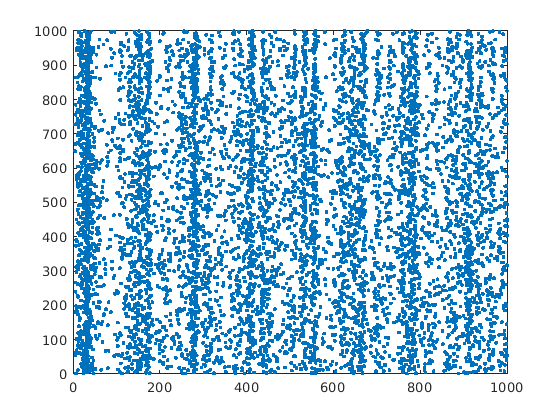

plot(firings(:,1),firings(:,2),'.');

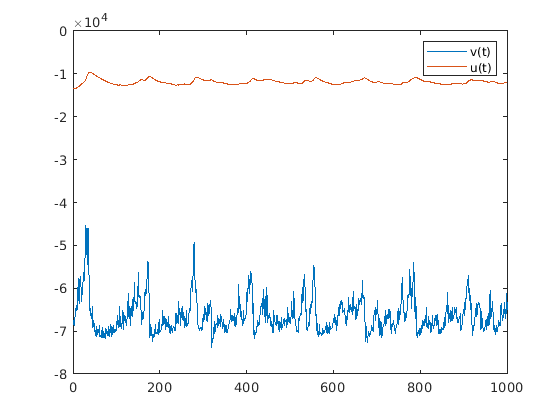

plot(1:steps, state)
legend('v(t)','u(t)')